# Digits Rec

Date: 5/2017

Data Source: Kaggle.com

## Understand Business Goals 

Objectives:

- Recognize digits by pixels

## Prepare and Understand Data

Clean Up

clear
clc
close all


Load Data

data = readtable('train.csv');
predictData = readtable('test.csv');

Statistical summaries

summary(data);


Variables:

    label: 42000×1 double

        Values:

            Min       0      
            Median    4      
            Max       9      

    pixel0: 42000×1 double

        Values:

            Min       0       
            Median    0       
            Max       0       

    pixel1: 42000×1 double

        Values:

            Min       0       
            Median    0       
            Max       0       

    pixel2: 42000×1 double

        Values:

            Min       0       
            Median    0       
            Max       0       

    pixel3: 42000×1 double

        Values:

            Min       0       
            Median    0       
            Max       0       

    pixel4: 42000×1 double

        Values:

            Min       0       
            Median    0       
            Max       0       

    pixel5: 42000×1 double

        Va

summary(predictData);


Variables:

    pixel0: 28000×1 double

        Values:

            Min       0       
            Median    0       
            Max       0       

    pixel1: 28000×1 double

        Values:

            Min       0       
            Median    0       
            Max       0       

    pixel2: 28000×1 double

        Values:

            Min       0       
            Median    0       
            Max       0       

    pixel3: 28000×1 double

        Values:

            Min       0       
            Median    0       
            Max       0       

    pixel4: 28000×1 double

        Values:

            Min       0       
            Median    0       
            Max       0       

    pixel5: 28000×1 double

        Values:

            Min       0       
            Median    0       
            Max       0       

    pixel6: 28000×1 double

      

Feature Engineering (Drop/Create/Convert/Complete)

% Check for missing data
if(nnz(ismissing(data)))
    figure
    imagesc(ismissing(data))
    ax = gca;
    varsTrain = data.Properties.VariableNames;
    ax.XTick = 1:length(varsTrain);
%     ax.XTickLabel = vars;
%     ax.XTickLabelRotation = 90;
end
% Check for missing predictData data
if(nnz(ismissing(predictData)))
    figure
    imagesc(ismissing(predictData))
    ax = gca;
    varsTest = predictData.Properties.VariableNames;
    ax.XTick = 1:length(varsTest);
%     ax.XTickLabel = vars;
%     ax.XTickLabelRotation = 90;
end
% Remove
% Replace
% Convert
% Create
% Double check missing data
if ((nnz(ismissing(data))+nnz(ismissing(predictData)))~=0)
    warning('There are missing data. Check!')
end

Exploratory Analysis and Visualizations

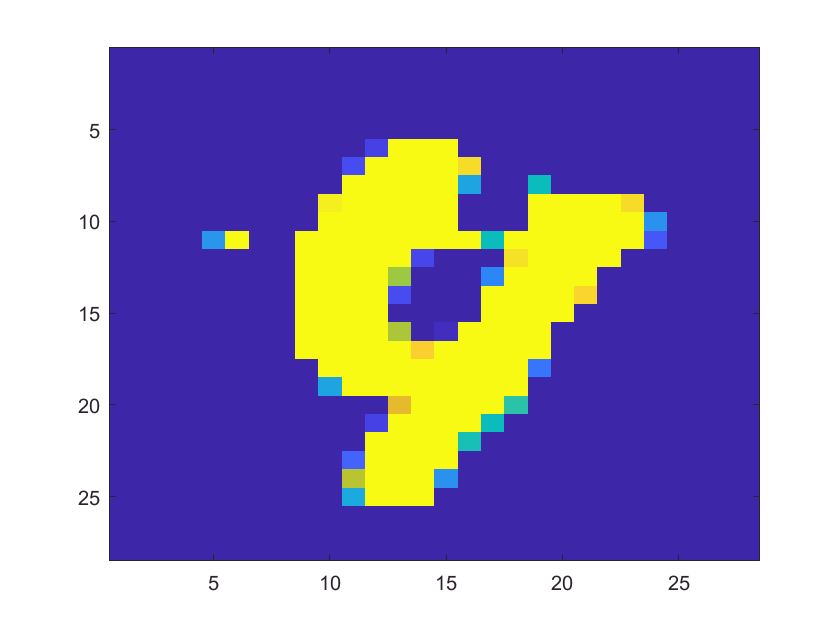

% show image
n = randi([1,size(data,1)]);
d = reshape(data{n,2:end}',28,28)';
image(d)

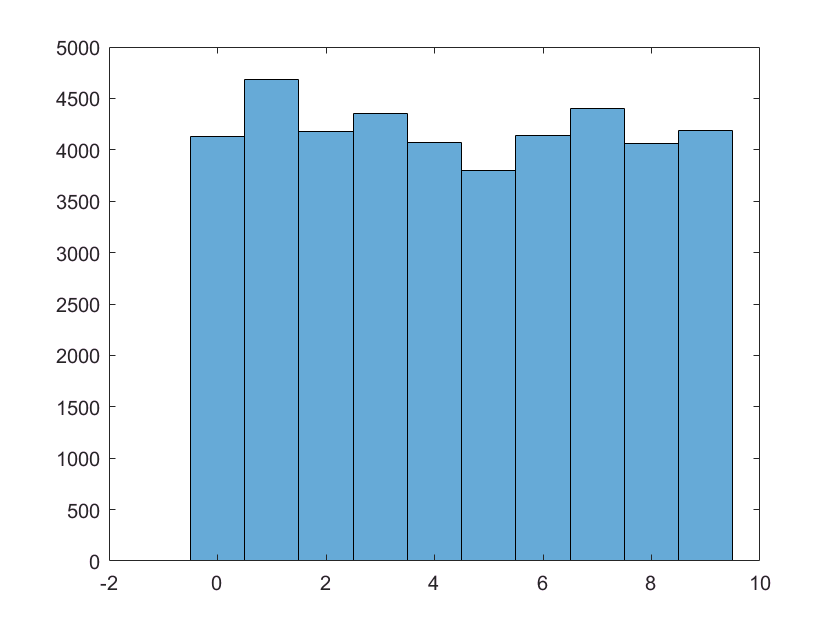


% histogram of labels
histogram(data{:,1})

Correlation of variables

% figure
% imagesc(corr(data{:,:}))
% colorbar
% ax = gca;
% vars = data.Properties.VariableNames;
% ax.XTick = 1:length(vars);
% ax.YTick = 1:length(vars);
% ax.XTickLabel = vars;
% ax.YTickLabel = vars;
% ax.XTickLabelRotation = 45;
% ax.XAxisLocation = 'top'

Train and Test Data Preperation

% Use cross validation partition
c = cvpartition(size(data,1),'HoldOut',0.3);
trainData = data(training(c),:);
testData = data(test(c),:);

Predict and Response Variables

responseVar = 'label';
vars = data.Properties.VariableNames;
predictVars = setdiff(vars,{responseVar});

PCA preperation

% PCA components and dimension
[pcoeff,pscore,~,~,pexp] = pca(data{:,predictVars});

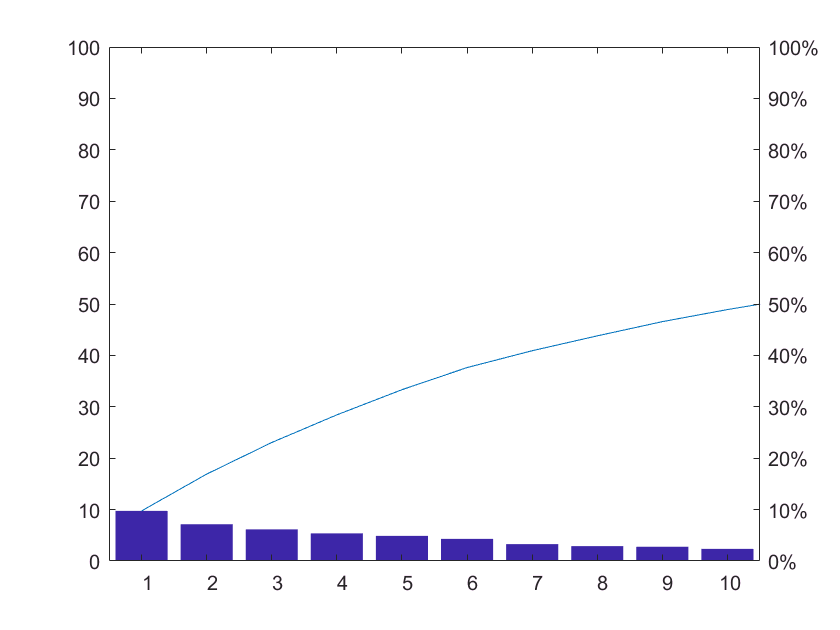

pareto(pexp);

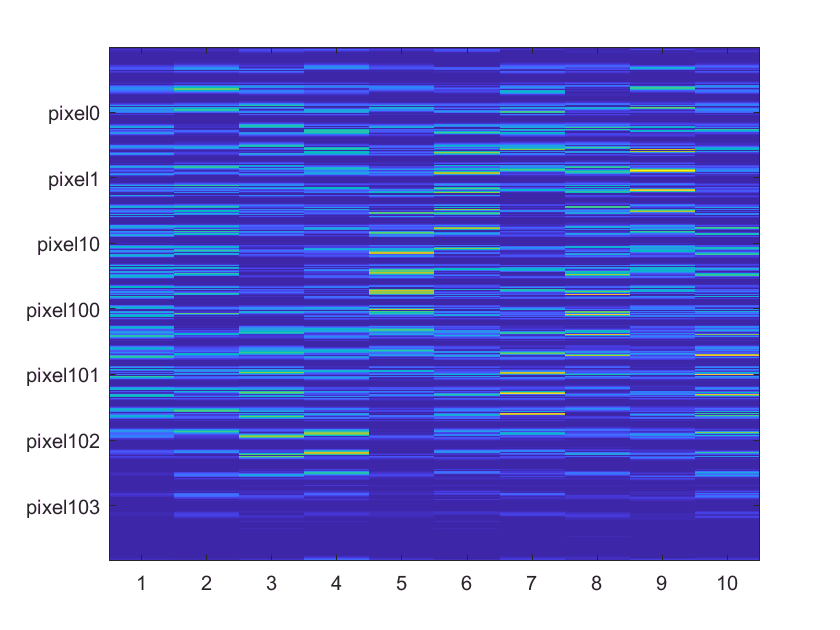

pcaD = 10;
% Show components dependancy
figure
imagesc(abs(pcoeff(:,1:pcaD)));
ax = gca;
ax.XTick = 1:pcaD;
ax.YTickLabel = predictVars;

% PCA train and test data
pcaTrain = pscore(training(c),1:pcaD);
pcaTrainResponse = data{training(c),responseVar};
pcaTest = pscore(test(c),1:pcaD);
pcaTestResponse = data{test(c),responseVar};
% Create prediction data in terms of new components
mu = mean(data{:,predictData.Properties.VariableNames});
pcaPredictData = (predictData{:,:}-mu)*pcoeff(:,1:pcaD); 

Create a structure to store all models

DA = struct;

## Choose Algorithm - Fit, Evaluate and Update Model

Classification

- K-nearest Neighbors

%%Fit
nNeighbors = 5;
mdl = fitcknn(trainData,responseVar,'NumNeighbors',nNeighbors,'Standardize',1);
DA.KNN = mdl;

%%Evaluate
% Model Performence
err = loss(mdl,testData)

err = 0.0620

% Cross Validation
kFold = 5;
% mdlCV = fitcknn(trainData,responseVar,'NumNeighbors',nNeighbors,'Standardize',1,'kFold',kFold);
% errCV = kfoldLoss(mdlCV)

%%Update
% PCA
[mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,@fitcknn)

mdlPCA =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
          NumObservations: 29400
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedModel
    CrossValidatedModel: 'KNN'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'}
           ResponseName: 'Y'
        NumObservations: 29400
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1 2 3 4 5 6 7 8 9]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.0802

errCV = 0.0838

DA.pcaKNN = mdlPCA;
% Feature Selection
% [mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,@fitcknn)
% DA.fsKNN = mdlFS;
% Ensemble Leanring
% mdlEn = fitensemble(trainData,responseVar,'Subspace',40,'KNN');
% err = loss(mdlEn,testData)
% DA.elKNN = mdlEn;
% Multiclass Method
template = templateKNN('NumNeighbors',nNeighbors,'Standardize',1);
[mdl,mdlCV,err,errCV] = mcFun(trainData,testData,responseVar,template,kFold)

Undefined function or variable 'kFold'.

DA.mcKNN = mdl;

- Classification Trees  

%%Fit
mdl = fitctree(trainData,responseVar);
% view(mdl,'mode','graph')
% Prune the tree
% mdlPrune = prune(mdl,'Level',1);
% view(mdlPrune,'mode','graph')
DA.cTree = mdl;

%%Evaluate
% Model Performence
err = loss(mdl,testData)

err = 0.1528

% err = loss(mdlPrune,testData)
% Cross Validation
% kFold = 5;
% mdlCV = fitctree(trainData,responseVar,'kFold',kFold);
% errCV = kfoldLoss(mdlCV)

%%Update
% PCA
[mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,@fitctree)

mdlPCA =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
          NumObservations: 29400


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'}
           ResponseName: 'Y'
        NumObservations: 29400
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1 2 3 4 5 6 7 8 9]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.1860

errCV = 0.1938

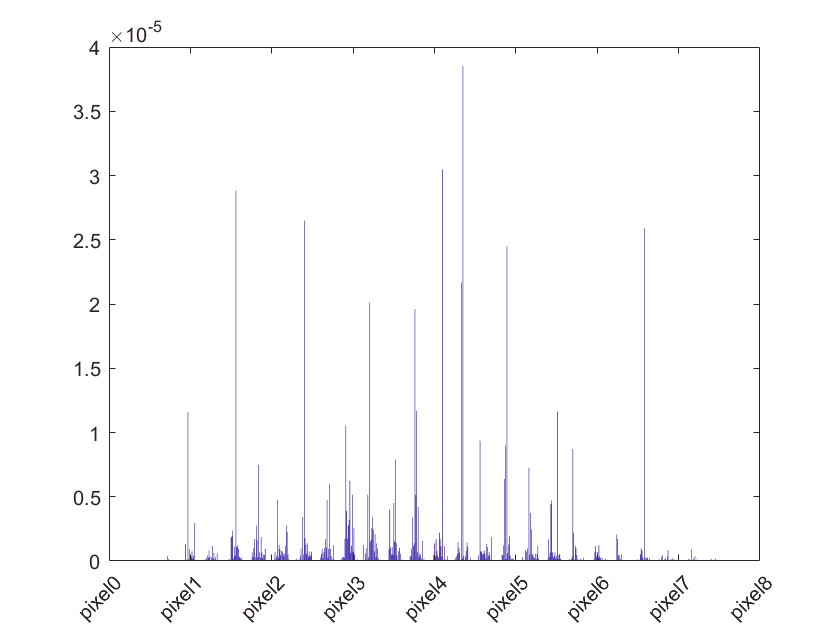

DA.pcaCTree = mdlPCA;
% Feature Importance
figure
p = predictorImportance(mdl);
bar(p);
ax = gca;
ax.XTickLabel = mdl.PredictorNames;
ax.XTickLabelRotation = 45;

toKeep = p>0.5e-5;
mdlFI = fitctree(trainData{:,toKeep},trainData{:,responseVar});
err = loss(mdlFI,testData{:,toKeep},testData{:,responseVar})

err = 0.2027

DA.fiCTree = mdlFI;
% Feature Selection
% [mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,@fitctree)
% DA.fsCTree = mdlFS;
% Ensemble Learning
% mdlEL = fitensemble(trainData,responseVar,'Bag',200,'Tree','Type','Classification');
% figure
% plot(loss(mdlEL,testData,'mode','cumulative'));
% [err,idx] = min(loss(mdlEL,testData,'mode','cumulative'))
% DA.elCTree = mdlEL;
% Multiclass Method
template = templateTree();
[mdl,mdlCV,err,errCV] = mcFun(trainData,testData,responseVar,template,kFold)

Undefined function or variable 'kFold'.

DA.mcCTree = mdl;

- Gaussian Naive Bayes

% %%Fit
% mdl = fitcnb(trainData,responseVar,'DistributionNames','normal');
% DA.NB = mdl;
% 
% %%Evaluate
% % Model Performence
% err = loss(mdl,testData)
% % Cross Validation
% kFold = 5;
% mdlCV = fitcnb(trainData,responseVar,'kFold',kFold);
% errCV = kfoldLoss(mdlCV)
% 
% %%Update
% % PCA
% [mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,@fitcnb)
% DA.pcaNB = mdlPCA;
% % Feature Seletion
% [mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,@fitcnb)
% DA.fsNB = mdlFS;
% % Multiclass Method
% template = templateNaiveBayes('DistributionNames','normal');
% [mdl,mdlCV,err,errCV] = mcFun(trainData,testData,responseVar,template,kFold)
% DA.mcNB = mdl;

- Discriminant Analysis

% %%Fit
% mdl = fitcdiscr(trainData,responseVar,'DiscrimType','linear');
% DA.Discr = mdl;
% 
% %%Evaluate
% % Model Performence
% err = loss(mdl,testData)
% % Cross Validation
% kFold = 5;
% mdlCV = fitcdiscr(trainData,responseVar,'kFold',kFold);
% errCV = kfoldLoss(mdlCV)
% 
% %%Update
% % PCA
% [mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,@fitcdiscr)
% DA.pcaDiscr = mdlPCA;
% % Feature Seletion
% [mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,@fitcdiscr)
% DA.fsDiscr = mdlFS;
% % Ensemble Learning
% mdlEL = fitensemble(trainData,responseVar,'Bag',200,'Discriminant');
% figure
% plot(loss(mdlEL,testData,'mode','cumulative'));
% [err,idx] = min(loss(mdlEL,testData,'mode','cumulative'))
% DA.elDiscr = mdlEL;
% % Multiclass Method
% template = templateDiscriminant('DiscrimType','linear');
% [mdl,mdlCV,err,errCV] = mcFun(trainData,testData,responseVar,template,kFold)
% DA.mcDiscr = mdl;

- SVM

%%Fit
% mdl = fitcsvm(trainData,responseVar,'kernelFunction','gaussian','Standardize',1);
% DA.cSVM = mdl;

%%Evaluate
% Model Performence
% err = loss(mdl,testData)
% % Cross Validation
kFold = 5;
% mdlCV = fitcsvm(trainData,responseVar,'kFold',kFold,'KernelFunction','gaussian','Standardize',1);
% errCV = kfoldLoss(mdlCV)

%%Update
% PCA
% [mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,@fitcsvm)
% DA.pcaCSVM = mdlPCA;
% Feature Seletion
% [mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,@fitcsvm)
% DA.fsCSVM = mdlFS;
% Multiclass Method
template = templateSVM('KernelFunction','gaussian','Standardize',1);
[mdl,mdlCV,err,errCV] = mcFun(trainData,testData,responseVar,template,kFold)
DA.mcCSVM = mdl;

Neural Networks

- Self-Organizing Maps

% net = selforgmap([10,10]);
% X = data{:,predictVars}';
% net = train(net,X);
% figure
% plotsomhits(net,X)
% plotsomnd(net,X)
% plotsomplanes(net,X)
% preds = net(predictData{:,:}');

- Feed-Forward Networks

X = data{:,predictVars};
targets = data{:,responseVar};
Xnew = predictData{:,:};
% net = patternnet(3);
net = fitnet([5,2],'trainrp');
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
[net,tr] = train(net,X',targets');
preds = net(Xnew');

- CNN

xdata = data;
xdata.label = categorical(data.label);
layers = [imageInputLayer([28 28 1]);
          convolution2dLayer(5,16);
          reluLayer();
          maxPooling2dLayer(2,'Stride',2);
          fullyConnectedLayer(3);
          softmaxLayer();
          classificationLayer()];
options = trainingOptions('sgdm');
net = trainNetwork(data,layers,options);

Error using trainNetwork>iAssertValidClassificationTable (line 840)
Invalid input table for classification. Predictors must be in the first column of the table, as image paths or images. Responses must be after the first column, as categorical labels.

Error in trainNetwork>iAssertValidTable (line 825)
    iAssertValidClassificationTabl

preds = classify(net,predictData);

## Make Predictions

% Predict classification model
% preds = predict(DA.KNN,predictData);
% Predict classification PCA model
% preds = predict(DA.pcaKNN,pcaPredictData);
% NN
Label = round(preds)';
Label = min(max(Label,0),9);
ImageId = (1:length(Label))'

ImageId =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


subTable = table(ImageId,Label);
writetable(subTable,'submission.csv');

## **Function Define**

function [mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,fitFun)   
    % PCA Function
    
    if(isequal(fitFun,@fitcknn)) 
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'NumNeighbors',5,'Standardize',1);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'NumNeighbors',5,'Standardize',1,'crossval','on');
    elseif(isequal(fitFun,@fitctree))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on');
    elseif(isequal(fitFun,@fitcnb))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'Distribution','normal');
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on','Distribution','normal');
    elseif(isequal(fitFun,@fitcdiscr))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'DiscrimType','linear');
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on','DiscrimType','linear');
    elseif(isequal(fitFun,@fitcsvm))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'KernelFunction','gaussian','Standardize',1);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on','KernelFunction','gaussian','Standardize',1);
    elseif(isequal(fitFun,@fitcecoc))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on');
    elseif(isequal(fitFun,@fitrtree))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on');
    elseif(isequal(fitFun,@fitrsvm))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'KernelFunction','gaussian','Standardize',1);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on','KernelFunction','gaussian','Standardize',1);
    end
    err = loss(mdlPCA,pcaTest,pcaTestResponse);
    errCV = kfoldLoss(mdlCV);  
end


function [mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,fitFun)
    % Feature Select Function
    
    errorFun = @(Xtrain,ytrain,Xtest,ytest) nnz(ytest ~= predict(fitFun(Xtrain,ytrain),Xtest));
    toKeep = sequentialfs(errorFun,data{:,predictVars},data{:,responseVar},'cv',kFold);
    vars(toKeep)
    if(isequal(fitFun,@fitcknn)) 
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'NumNeighbors',5,'Standardize',1);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'NumNeighbors',5,'Standardize',1,'crossval','on');
    elseif(isequal(fitFun,@fitctree))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on');
    elseif(isequal(fitFun,@fitcnb))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'Distribution','normal');
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on','Distribution','normal');
    elseif(isequal(fitFun,@fitcdiscr))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'DiscrimType','linear');
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on','DiscrimType','linear');
    elseif(isequal(fitFun,@fitcsvm))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'KernelFunction','gaussian','Standardize',1);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on','KernelFunction','gaussian','Standardize',1);
    elseif(isequal(fitFun,@fitcecoc))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on');
    elseif(isequal(fitFun,@fitrtree))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on');
    elseif(isequal(fitFun,@fitrsvm))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'KernelFunction','gaussian','Standardize',1);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on','KernelFunction','gaussian','Standardize',1);
    end
    err = loss(mdlFS,testData);
    errCV = kfoldLoss(mdlCV);  
end

function [mdl,mdlCV,err,errCV] = mcFun(trainData,testData,responseVar,template,kFold)
    % Multiclass Function   
    mdl = fitcecoc(trainData,responseVar,'Learners',template);
    err = loss(mdl,testData)
    mdlCV = fitcecoc(trainData,responseVar,'Learners',template,'kFold',kFold);
    errCV = kfoldLoss(mdlCV) 
end

function yPred =  predictRidgeResponse(mdl,xTest,xTrain,yTrain)
    % Make predictions
    % To make predictions with original data, need to shift coefficients back
    % to unscaled data (RIDGE normalizes data by default)
    m = mean(xTrain);
    s = std(xTrain,0,1)';   
    % (un)Scale b
    bUS = bsxfun(@rdivide,mdl,s);
    % Calculate constant term (from scaling)
    intercept = mean(yTrain)-m*bUS;
    % Make predictions
    yPred = xTest*bUS+intercept;
end
